# MECH 320 Finite Element Method Project

## Introduction

The finite element method is a numerical method for solving partial differential equations to solve complicated structural analysis, heat transfer, or fluid flow problems. This method works by solving equations that are approximations of the original partial differential equations over small local lengths, areas, or volumes. Turning a solid object into a finite number of elements is called discretization and it creates a mesh over the given space. Then the results of each individual element can be combined with its neighbouring element until a large system of equations is formed. The solution is found by solving the system for the entire solid body using the initial conditions. The goal of this report is to gain experience in this method in the context of stress and strain analysis on solid bodies. The report also aims to find the stress concentration factor of rectangular bars with holes and compare the results of the FEM models with the results from analytical and experimental methods.

The two types of stress concentrations being considered in this report are circular and elliptical holes in rectangular bars of different geometries (see Figure 1).

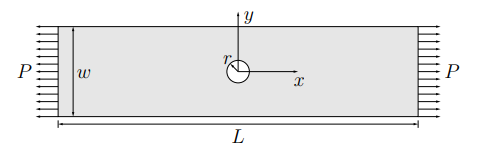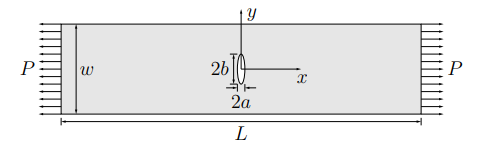

*Figure 1. Reference Geometries*

A tensile force is applied to the bars and their dimensions are characterized as shown in Figure 1. The theoretical equation for these types of stress concentrations are dictated by an equation that will be used to compare the theoretical and modelled results for every type of geometry. The results from the photoelasticity lab conducted earlier in the semester are only comparable to the 38mm wide bar with the circular hole as is discussed in the results section.

## Results

The model is initialized with the plate geometry, material properties, mesh properties, and the applied load.

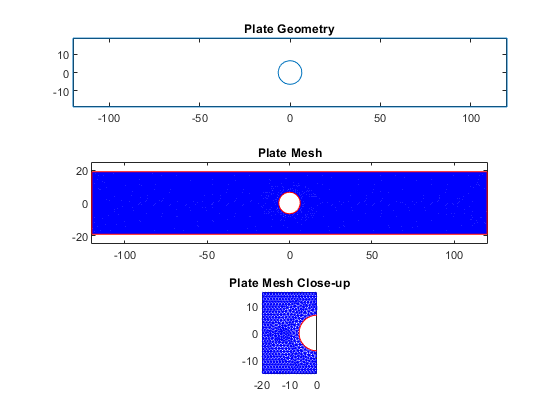


clear all
close all

%% 1: Model parameters
half_crack_height = 6.5;       % Half crack height (mm)
half_crack_width = 1;        % Half crack width (mm)
half_width = 38/2;              % Plate half width (mm)
half_length = 240/2;             % Plate half length (mm)
youngs_modulus = 200*10^3;          % Youngs Modulus of material (MPa)
poissons_ratio = 0.3;          % Poissons ration of material

surf_traction = 10;           % Surface traction (N/mm)
mesh_size = half_crack_height/6; % Mesh refinement (no need to change)

plot_scale_factor = 1;       % Scale factor for plotting deformations, adjust it to be able to visualize contraction of the plate near the hole


% Vector representing rectangular plate geometry
plate = [3 4 -half_length half_length half_length -half_length -half_width -half_width half_width half_width]';

% Vector representing circular or elliptical hole geometry
hole = [1 0 0 half_crack_height]';
hole = [hole;zeros(length(plate)-length(hole),1)];

% Define geometry description matrix (GDM) as a subtraction operation between hole and bar
gdm = [plate, hole];                   % Form the GDM containing all the shapes
names = char('bar','hole')';          % Give names to shapes
geom = decsg(gdm,'bar - hole',names); % Boolean subtraction of hole from bar

%% 3: FEM model (no need to modify this section)
model = createpde('structural','static-planestress');

% Create geometry and include it into the structural model
geometryFromEdges(model,geom);

% Specify material properties
structuralProperties(model,'YoungsModulus',youngs_modulus,'PoissonsRatio',poissons_ratio);

% Apply boundary conditions
structuralBC(model,'Edge',3,'XDisplacement',0);
structuralBC(model,'Vertex',3,'YDisplacement',0);
structuralBoundaryLoad(model,'Edge',1,'SurfaceTraction',[surf_traction;0]);

% Generate mesh
generateMesh(model,'Hmax',mesh_size);

% Solve system of equations
sol = solve(model);

%% 4: Plotting

figure
tiledlayout(3,1)
nexttile          % Create figure
pdegplot(model); % Plot model geometry
axis equal       % Set equal scales for x and y axes
title('Plate Geometry');    % Plot title

% Mesh
nexttile
pdemesh(model); % Plot model mesh
axis equal    % Set equal scales for x and y axes
title('Plate Mesh');   % Plot title

%Mesh Close up
nexttile
pdemesh(model); % Plot model mesh
xlim([-20 0]);
ylim([-15 15]);
title('Plate Mesh Close-up');   % Plot title
hold on

*                                           Figure 2: Plate Geometry and Mesh*

Then we find the stress and displacement distribution created by the applied load P

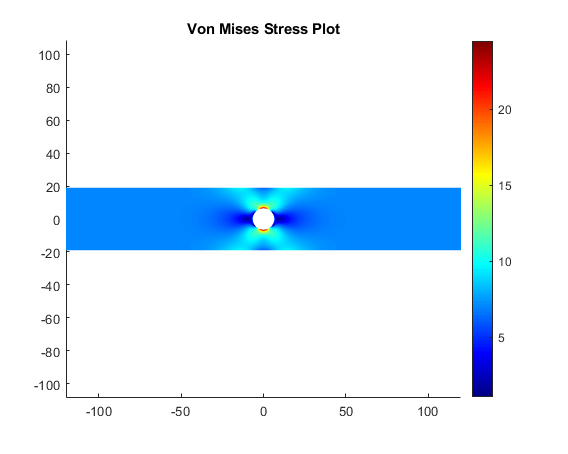

% Von Mises stress contours
svon = 0.5.*sqrt((sol.Stress.sxx-sol.Stress.syy).^2+(0-sol.Stress.sxx).^2+6*(sol.Stress.sxy).^2);   % Calculate von Mises stress

figure                                         % Create figure
pdeplot(model,'XYData',svon,'ColorMap','jet'); % Plot xy data (in this case the von Mises stress)
axis equal                                     % Set equal scales for x and y axes
title('Von Mises Stress Plot');                     % Plot title

*                                          Figure 3: Plate Von Mises Stress Plot*

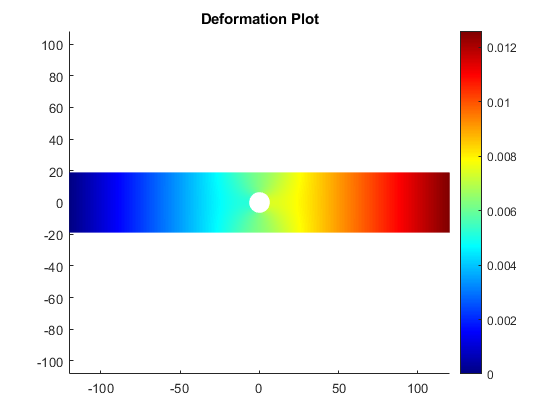

% Deformed shape
figure                                         % Create figure
pdeplot(model,"XYData",sol.Displacement.x,"Deformation",sol.Displacement,"DeformationScaleFactor",plot_scale_factor,"ColorMap","jet"); % Plot xy data (in this case displacement and deformation superimposed)
axis equal                                     % Set equal scales for x and y axes
title('Deformation Plot');                    % Plot title

*                                           Figure 4: Plate Deformation Plot*

The stress concentration factor is defined as follows for a bar with a hole:


$$\sigma_{\max } =K\sigma_o =K\;\frac{F}{A}=K\;\frac{P\;t}{\left(w-2a\right)t}=K\;\frac{P}{\left(w-2a\right)}$$


We can solve for the stress concentration factor in terms of values obtained through the problem definition and the model


$$K=\sigma_{\max } \frac{\left(w-2a\right)}{P}$$


We can use theoretical method employed in the Photoelasticity lab to find the theoretical nominal and max stresses. Both calculations are shown below.

%% 5: Calculate stress concentration factor

p = [-100,0];                         % Coordinates of point far away from the hole
snom = interpolateStress(sol,p').xx; % Nominal stress x obtained at point far away from hole

smax = max(sol.Stress.sxx)  ;      % Maximum normal stress x in the plate
k_fem = smax/snom;
r = half_crack_width;
theta = pi/2;
snom_thoery = surf_traction/(2*half_width); 
s_r = 0.5*snom_thoery*((1+3-4)*cos(2*theta)); %radial stress at top of hole
s_theta = 0.5*snom_thoery*((1+1)-(1+3)*cos(2*theta)); %tangential stress at top of hole
t_rtheta = -0.5*snom_thoery*(1-3+2)*sin(2*theta); %shear stress at top of hole

smax_theory = s_r*cos(theta)^2+s_theta*sin(theta)^2-2*t_rtheta*sin(theta)*cos(theta);

k_theory = smax_theory/snom_thoery;

%photo elasticity data from 162.75N applied to bar with hole
snom_photo = 0.75; %photoelasticy nominal stress [MPa]
smax_photo = 3.04; %photoelasticy max stress [MPa] ie. stress at edge of hole

k_photo = smax_photo/snom_photo;

fprintf("k_model = %d\nk_theory=%d\nk_photo=%d\n",k_fem,k_theory,k_photo);               % Print k to the console

k_model = 3.480600e+00
k_theory=3
k_photo=4.053333e+00


The width of the plate is then increased to 240mm and a mesh is created. The von Mises stresses and deformation is also plotted. 

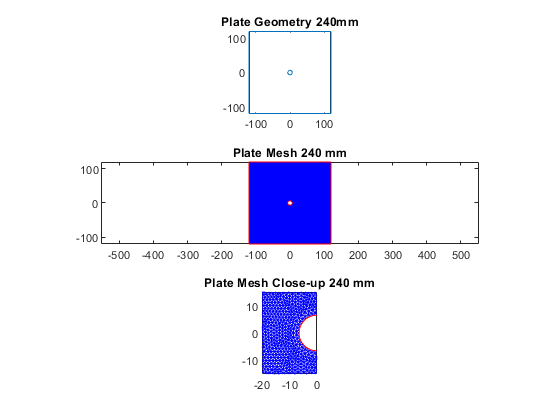

%% 5: Calculate stress concentration factor
half_width2 = 240/2;                        % new half width of geometry

surf_traction = 10;           % Surface traction (N/mm)
mesh_size = half_crack_height/6; % Mesh refinement (no need to change)

plot_scale_factor = 1;       % Scale factor for plotting deformations, adjust it to be able to visualize contraction of the plate near the hole


% New Vector representing rectangular plate geometry
plate2 = [3 4 -half_length half_length half_length -half_length -half_width2 -half_width2 half_width2 half_width2]';

% Vector representing circular or elliptical hole geometry
hole = [1 0 0 half_crack_height]';
hole = [hole;zeros(length(plate)-length(hole),1)];

% Define geometry description matrix (GDM) as a subtraction operation between hole and bar
gdm = [plate2, hole];                   % Form the GDM containing all the shapes
names = char('bar','hole')';          % Give names to shapes
geom = decsg(gdm,'bar - hole',names); % Boolean subtraction of hole from bar

%% 3: FEM model (no need to modify this section)
model2 = createpde('structural','static-planestress');

% Create geometry and include it into the structural model
geometryFromEdges(model2,geom);

% Specify material properties
structuralProperties(model2,'YoungsModulus',youngs_modulus,'PoissonsRatio',poissons_ratio);

% Apply boundary conditions
structuralBC(model2,'Edge',3,'XDisplacement',0);
structuralBC(model2,'Vertex',3,'YDisplacement',0);
structuralBoundaryLoad(model2,'Edge',1,'SurfaceTraction',[surf_traction;0]);

% Generate mesh
generateMesh(model2,'Hmax',mesh_size);

% Solve system of equations
sol2 = solve(model2);

%% 4: Plotting

figure
tiledlayout(3,1)
% Geometry
nexttile          % Create figure
pdegplot(model2); % Plot model geometry
axis equal       % Set equal scales for x and y axes
title('Plate Geometry 240mm');    % Plot title

% Mesh
nexttile
pdemesh(model2); % Plot model mesh
axis equal    % Set equal scales for x and y axes
title('Plate Mesh 240 mm');   % Plot title

%Mesh Close up
nexttile
pdemesh(model2); % Plot model mesh
xlim([-20 0]);
ylim([-15 15]);
title('Plate Mesh Close-up 240 mm');   % Plot title

*                                            Figure 5: 240mm Plate Geometry and Mesh*

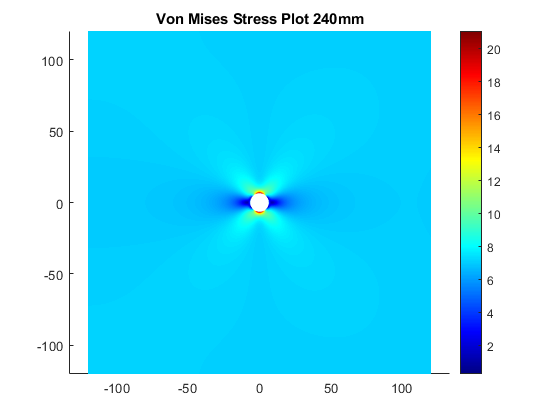

% Von Mises stress contours
svon2 = 0.5.*sqrt((sol2.Stress.sxx-sol2.Stress.syy).^2+(0-sol2.Stress.sxx).^2+6*(sol2.Stress.sxy).^2);   % Calculate von Mises stress

figure                                         % Create figure
pdeplot(model2,'XYData',svon2,'ColorMap','jet'); % Plot xy data (in this case the von Mises stress)
axis equal                                     % Set equal scales for x and y axes
title('Von Mises Stress Plot 240mm');                     % Plot title

*                                        Figure 6: 240mm Plate Von Mises Stress Plot*

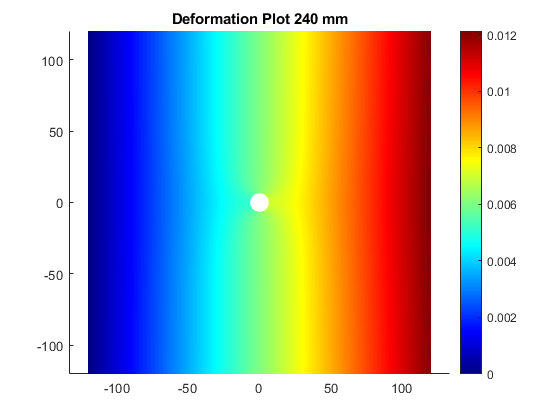

% Deformed shape
figure                                         % Create figure
pdeplot(model2,"XYData",sol2.Displacement.x,"Deformation",sol2.Displacement,"DeformationScaleFactor",plot_scale_factor,"ColorMap","jet"); % Plot xy data (in this case displacement and deformation superimposed)
axis equal                                     % Set equal scales for x and y axes
title('Deformation Plot 240 mm');                    % Plot title

*                                        Figure 7: 240mm Plate Deformation Plot*

The stress concentration factor K is then calculated using the formulas below as before. 


$$\sigma_{\max } =K\sigma_o =K\;\frac{F}{A}=K\;\frac{P\;t}{\left(w-2a\right)t}=K\;\frac{P}{\left(w-2a\right)}$$



$$K=\sigma_{\max } \frac{\left(w-2a\right)}{P}$$


We can use theoretical method employed in the Photoelasticity lab to find the theoretical nominal and max stresses. Both calculations are shown below.

% Von Mises stress contours
svon2 = 0.5.*sqrt((sol2.Stress.sxx-sol2.Stress.syy).^2+(0-sol2.Stress.sxx).^2+6*(sol2.Stress.sxy).^2);   % Calculate von Mises stress

%% 5: Calculate stress concentration factor

p = [-100,0];                         % Coordinates of point far away from the hole
snom2 = interpolateStress(sol2,p').xx; % Nominal stress x obtained at point far away from hole

smax2 = max(sol2.Stress.sxx)  ;      % Maximum normal stress x in the plate
k_fem2 = smax2/snom2;
r = half_crack_width;
theta = pi/2;
snom_thoery2 = surf_traction/(2*half_width2); 
s_r2 = 0.5*snom_thoery2*((1+3-4)*cos(2*theta)); %radial stress at top of hole
s_theta2 = 0.5*snom_thoery2*((1+1)-(1+3)*cos(2*theta)); %tangential stress at top of hole
t_rtheta2 = -0.5*snom_thoery2*(1-3+2)*sin(2*theta); %shear stress at top of hole

smax_theory2 = s_r2*cos(theta)^2+s_theta2*sin(theta)^2-2*t_rtheta2*sin(theta)*cos(theta);

k_theory2 = smax_theory2/snom_thoery2;


fprintf("k_model(240mm) = %d\nk_theory(240mm)=%d\n",k_fem2,k_theory2);% Print k to the console

k_model(240mm) = 3.031069e+00
k_theory(240mm)=3


### Eliptical Hole

The same procedure is repeated for the bar with an elliptical hole. The plate is first intialized using the reference geometery, a mesh is then applied. 

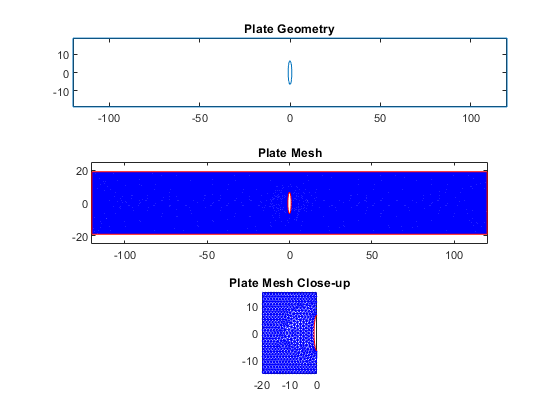

clc

%% 1: Model parameters
half_crack_height = 6.5;     % Half crack height (mm)
half_crack_width = 1;        % Half crack width (mm)
half_width = 38/2;           % Plate half width (mm)
half_length = 240/2;         % Plate half length (mm)
youngs_modulus = 200*10^3;   % Youngs Modulus of material (MPa)
poissons_ratio = 0.3;        % Poissons ration of material

surf_traction = 10;              % Surface traction (N/mm)
mesh_size = half_crack_height/6; % Mesh refinement (no need to change)

plot_scale_factor = 1;       % Scale factor for plotting deformations, adjust it to be able to visualize contraction of the plate near the hole


% Vector representing rectangular plate geometry
plate = [3 4 -half_length half_length half_length -half_length -half_width -half_width half_width half_width]';

% Vector representing circular or elliptical hole geometry
hole = [4 0 0 half_crack_width half_crack_height]';
hole = [hole;zeros(length(plate)-length(hole),1)];

% Define geometry description matrix (GDM) as a subtraction operation between hole and bar
gdm = [plate, hole];                   % Form the GDM containing all the shapes
names = char('bar','hole')';          % Give names to shapes
geom = decsg(gdm,'bar - hole',names); % Boolean subtraction of hole from bar

%% 3: FEM model (no need to modify this section)
model = createpde('structural','static-planestress');

% Create geometry and include it into the structural model
geometryFromEdges(model,geom);

% Specify material properties
structuralProperties(model,'YoungsModulus',youngs_modulus,'PoissonsRatio',poissons_ratio);

% Apply boundary conditions
structuralBC(model,'Edge',3,'XDisplacement',0);
structuralBC(model,'Vertex',3,'YDisplacement',0);
structuralBoundaryLoad(model,'Edge',1,'SurfaceTraction',[surf_traction;0]);

% Generate mesh
generateMesh(model,'Hmax',mesh_size);

% Solve system of equations
sol = solve(model);

%% 4: Plotting

figure
tiledlayout(3,1)
% Geometry
nexttile          % Create figure
pdegplot(model); % Plot model geometry
axis equal       % Set equal scales for x and y axes
title('Plate Geometry');    % Plot title

% Mesh
nexttile
pdemesh(model); % Plot model mesh
axis equal    % Set equal scales for x and y axes
title('Plate Mesh');   % Plot title

%Mesh Close up
nexttile
pdemesh(model); % Plot model mesh
xlim([-20 0]);
ylim([-15 15]);
title('Plate Mesh Close-up');   % Plot title

*                                     Figure 8:  Plate with Elliptical Geometry and Mesh*

Again, select the stresses and compute the Von Mises stress distribution, and the deformed shape of the bar.

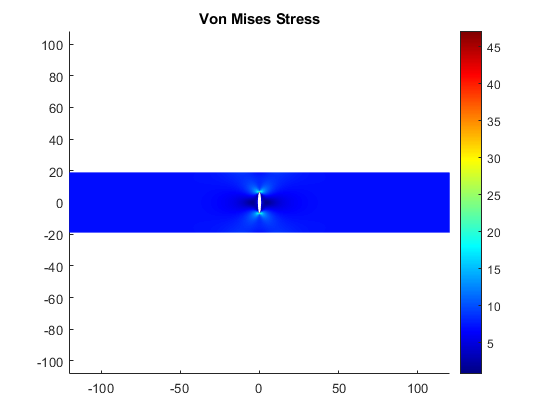

% Von Mises stress contours
svon = 0.5.*sqrt((sol.Stress.sxx-sol.Stress.syy).^2+(0-sol.Stress.sxx).^2+6*(sol.Stress.sxy).^2);   % Calculate von Mises stress

figure                                         % Create figure
pdeplot(model,'XYData',svon,'ColorMap','jet'); % Plot xy data (in this case the von Mises stress)
axis equal                                     % Set equal scales for x and y axes
title('Von Mises Stress');                     % Plot title

*                               Figure 9:  Plate with Elliptical hole von Mises Stress Plot*

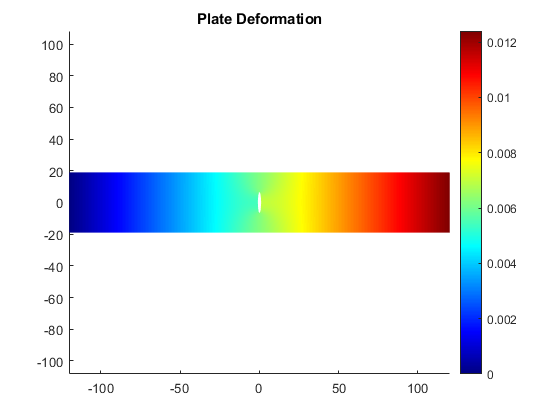

% Deformed shape
figure                                         % Create figure
pdeplot(model,"XYData",sol.Displacement.x,"Deformation",sol.Displacement,"DeformationScaleFactor",plot_scale_factor,"ColorMap","jet"); % Plot xy data (in this case displacement and deformation superimposed)
axis equal                                     % Set equal scales for x and y axes
title('Plate Deformation');                    % Plot title

*                               Figure 10: Plate with Elliptical hole Deformation Plot*

Finally, the stress concentration factor is computed and compared with the theoretical value. This time however, the theoretical stress concentration factor is computed using the formula provided in the lab manual:


$$K=1+2\left( \frac{a}{b} \right)$$
 

where $a$ and $b$ are the half minor and half major axis of the ellipse respectively.

%% 5: Calculate stress concentration factor
p = [-100,0];                                   % Coordinates of point far away from the hole
snom = interpolateStress(sol,p').xx;            % Nominal stress x obtained at point far away from hole
smax = max(sol.Stress.sxx);                     % Maximum normal stress x in the plate
k_theory = 1+2*(half_crack_height/half_crack_width);   % Stress concentration factor for ellipse
k_fem    = smax/snom;
fprintf("snom = %d\nsmax = %d\nk_theory = %d\nk_fem = %d\n", snom, smax, k_theory, k_fem);

snom = 1.000003e+01
smax = 7.751193e+01
k_theory = 14
k_fem = 7.751166e+00


This exact procedure is repeated for an ellipse with $a=3$ and $a=6$ to compare stress concentration factors. First, $a=3$:

clc

%% 1: Model parameters
half_crack_height = 6.5;     % Half crack height (mm)
half_crack_width = 3;        % Half crack width (mm)
half_width = 38/2;           % Plate half width (mm)
half_length = 240/2;         % Plate half length (mm)
youngs_modulus = 200*10^3;   % Youngs Modulus of material (MPa)
poissons_ratio = 0.3;        % Poissons ration of material

surf_traction = 10;              % Surface traction (N/mm)
mesh_size = half_crack_height/6; % Mesh refinement (no need to change)

plot_scale_factor = 1;       % Scale factor for plotting deformations, adjust it to be able to visualize contraction of the plate near the hole


% Vector representing rectangular plate geometry
plate = [3 4 -half_length half_length half_length -half_length -half_width -half_width half_width half_width]';

% Vector representing circular or elliptical hole geometry
hole = [4 0 0 half_crack_width half_crack_height]';
hole = [hole;zeros(length(plate)-length(hole),1)];

% Define geometry description matrix (GDM) as a subtraction operation between hole and bar
gdm = [plate, hole];                   % Form the GDM containing all the shapes
names = char('bar','hole')';          % Give names to shapes
geom = decsg(gdm,'bar - hole',names); % Boolean subtraction of hole from bar

%% 3: FEM model (no need to modify this section)
model = createpde('structural','static-planestress');

% Create geometry and include it into the structural model
geometryFromEdges(model,geom);

% Specify material properties
structuralProperties(model,'YoungsModulus',youngs_modulus,'PoissonsRatio',poissons_ratio);

% Apply boundary conditions
structuralBC(model,'Edge',3,'XDisplacement',0);
structuralBC(model,'Vertex',3,'YDisplacement',0);
structuralBoundaryLoad(model,'Edge',1,'SurfaceTraction',[surf_traction;0]);

% Generate mesh
generateMesh(model,'Hmax',mesh_size);

% Solve system of equations
sol = solve(model);

%% 5: Calculate stress concentration factor
p = [-100,0];                                   % Coordinates of point far away from the hole
snom = interpolateStress(sol,p').xx;            % Nominal stress x obtained at point far away from hole
smax = max(sol.Stress.sxx);                     % Maximum normal stress x in the plate
k_theory = 1+2*(half_crack_height/half_crack_width);   % Stress concentration factor for ellipse
k_fem    = smax/snom;
fprintf("snom = %d\nsmax = %d\nk_theory = %d\nk_fem = %d\n", snom, smax, k_theory, k_fem);

snom = 1.000007e+01
smax = 5.605128e+01
k_theory = 5.333333e+00
k_fem = 5.605090e+00


Finally $a=6$:

clc
%% 1: Model parameters
half_crack_height = 6.5;     % Half crack height (mm)
half_crack_width = 6;        % Half crack width (mm)
half_width = 38/2;           % Plate half width (mm)
half_length = 240/2;         % Plate half length (mm)
youngs_modulus = 200*10^3;   % Youngs Modulus of material (MPa)
poissons_ratio = 0.3;        % Poissons ration of material

surf_traction = 10;              % Surface traction (N/mm)
mesh_size = half_crack_height/6; % Mesh refinement (no need to change)

plot_scale_factor = 1;       % Scale factor for plotting deformations, adjust it to be able to visualize contraction of the plate near the hole


% Vector representing rectangular plate geometry
plate = [3 4 -half_length half_length half_length -half_length -half_width -half_width half_width half_width]';

% Vector representing circular or elliptical hole geometry
hole = [4 0 0 half_crack_width half_crack_height]';
hole = [hole;zeros(length(plate)-length(hole),1)];

% Define geometry description matrix (GDM) as a subtraction operation between hole and bar
gdm = [plate, hole];                   % Form the GDM containing all the shapes
names = char('bar','hole')';          % Give names to shapes
geom = decsg(gdm,'bar - hole',names); % Boolean subtraction of hole from bar

%% 3: FEM model (no need to modify this section)
model = createpde('structural','static-planestress');

% Create geometry and include it into the structural model
geometryFromEdges(model,geom);

% Specify material properties
structuralProperties(model,'YoungsModulus',youngs_modulus,'PoissonsRatio',poissons_ratio);

% Apply boundary conditions
structuralBC(model,'Edge',3,'XDisplacement',0);
structuralBC(model,'Vertex',3,'YDisplacement',0);
structuralBoundaryLoad(model,'Edge',1,'SurfaceTraction',[surf_traction;0]);

% Generate mesh
generateMesh(model,'Hmax',mesh_size);

% Solve system of equations
sol = solve(model);

%% 5: Calculate stress concentration factor
p = [-100,0];                                   % Coordinates of point far away from the hole
snom = interpolateStress(sol,p').xx;            % Nominal stress x obtained at point far away from hole
smax = max(sol.Stress.sxx);                     % Maximum normal stress x in the plate
k_theory = 1+2*(half_crack_height/half_crack_width);   % Stress concentration factor for ellipse
k_fem    = smax/snom;
fprintf("snom = %d\nsmax = %d\nk_theory = %d\nk_fem = %d\n", snom, smax, k_theory, k_fem);

snom = 1.000014e+01
smax = 3.641877e+01
k_theory = 3.166667e+00
k_fem = 3.641827e+00


## Discussion of Results

For the first geometry, the stress concentration factor was calculated to be 3.4806. The experimentally determined value from the photoelasticity lab was 4.0533. When the two values are compared to the thoeretical stress concentration of 3, it can be seen that the FEA result is more accurate. The value from the lab is subject to a high degree of experimental error which is most likely responsible for the signifcant deviation. The geometry plot, mesh plot, close-up plot, von Mises, and deformation plot for the plate can be found figures 2,3 and 4 respectively.

When the stress concentration was recalculated for the 240mm plate, the FEM result was 3.031. The value is significantly closer to the theoretical value. Since the new plate is larger with the same mesh calculation, it has a greater number of finite elements. Since the accuracy of the FEM calcualtion increases with the number of elements used in the calulation, the larger plate will yield more accurate results. This also shows why FEMs are completed by computers and not humans: the number of calculations needed for accuracy is much better suited to a computer.

The plots for the new plate (with width at 240 mm) can be found in figures 5,6 and 7 respectively.

A plot of the plate with an elliptical hole was then created and a mesh was applied. The width of the crack was initially 1mm as shown in figure 8. The von Mises stress distribution is then represented by solving the stress distribution and mapping the von Mises values. The corresponding displacement magnitudes are also shown in figure 9 and 10. 

The stress intensity factor is calculated using the equation shown below where $a$ and $b$ are the half minor and half major axis of the elipse respectively.


$$K=1+2\left( \frac{a}{b} \right)$$
 

The calculated theoretical value was found to be 14 while the FEM resulted in 7.75. When compared to the circle with a = 1mm, a significant variation is found. The variation can be accounted for by understanding that K is the ratio of maximum stress to nominal stress. The larger maximum stress experienced by the ellipse for the same nominal stress results in a larger stress concentration factor. 

When the half width of the crack is increased to 3mm, the theoretical stress concentration decreases to 5.33 and the FEM stress concentraton decreases to 5.609. The values decreases further when the half width of the crack is set to 6mm with the theoretical and FEM K values being 3.16 and 3.64 respectively. The increasing accuracy of the FEM model can clearly be attributed to the increase in crack width. This is due to the mesh size being related to the crack height which is fixed throughout the calculations. A very small feature such as a 1mm crack is dififcult to model accurately as the relative number of elements is lower for such small geometries. When the crack size is increased the number of elements in contact with the crack also increases which results in more accurate results. This relationship shows a clear limitation of the FEM method and the importance of using multiple techniques to verify results. 

## Concluding Remarks

The report detailed the succesful usage of the FEM methodology to model a plate with a crack and a plate with a hole while under axial tension. The von Mises stress distribution and plate deformation were also calculated for each geometry and represented graphically using a color map. The stress concentration factor for the plate with a hole was found to be relatively accurate when compared with the photoelastic method and thoeretical calculations. The stress concentration factor found using FEM for the plate with an elliptical hole in it was initially innacurate when compared to the thoeretical value. However, with increasing crack width the accuracy of the FEM model improved due to the larger number of elements on the feature.The project clearly demonstrated the practiality and potential limitations of using FEM. 

## References